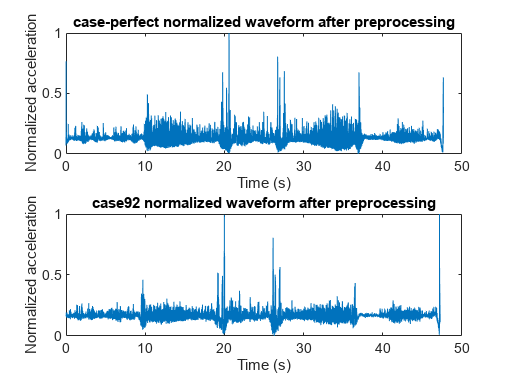

%% Data Preprocessing Script - Example
clear; clc;

%% Read and retain original column names
tblP = readtable('G0_P1_case_perfect.xls', ...
    'Sheet','Raw Data', 'VariableNamingRule','preserve');
timeP = tblP{:,1};
dataP = tblP{:,5};

tblC = readtable('G9_P1_case92.xls', ...
    'Sheet','Raw Data', 'VariableNamingRule','preserve');
timeC = tblC{:,1};
dataC = tblC{:,5};

%% Detrending
dataP_dt = detrend(dataP);
dataC_dt = detrend(dataC);

%% Bandpass filter design
fsP = 1/mean(diff(timeP));  nyqP = fsP/2;
fsC = 1/mean(diff(timeC));  nyqC = fsC/2;

% Your band parameters
f_low  = 1;   f_high = 100;

% Auto-correction
if f_high >= nyqP; f_high = 0.9*nyqP; end
WnP = [f_low, f_high] / nyqP;
[bP,aP] = butter(4, WnP);

if f_high >= nyqC; f_high = 0.9*nyqC; end
WnC = [f_low, f_high] / nyqC;
[bC,aC] = butter(4, WnC);

% --- Zero-phase filtering with mirrored extension to eliminate edge ringing ---
padT = 0.2;                
NpadP = round(padT * fsP);
NpadC = round(padT * fsC);

% case-perfect padding + filtfilt
tmpP = dataP_dt;
padP = [ flipud(tmpP(1:NpadP,:));
         tmpP;
         flipud(tmpP(end-NpadP+1:end,:)) ];
filtP_pad = filtfilt(bP, aP, padP);
dataP_filt = filtP_pad(NpadP+1:end-NpadP,:);

% case92 padding + filtfilt
tmpC = dataC_dt;
padC = [ flipud(tmpC(1:NpadC,:));
         tmpC;
         flipud(tmpC(end-NpadC+1:end,:)) ];
filtC_pad = filtfilt(bC, aC, padC);
dataC_filt = filtC_pad(NpadC+1:end-NpadC,:);

% --- Normalization (0–1) ---
normP = (dataP_filt - min(dataP_filt)) ./ ( max(dataP_filt) - min(dataP_filt) );
normC = (dataC_filt - min(dataC_filt)) ./ ( max(dataC_filt) - min(dataC_filt) );

% --- Save preprocessed results ---
save('preprocessed_case_perfect.mat','timeP','normP');
save('preprocessed_case92.mat'   ,'timeC','normC');

% --- Simple visualization check ---
figure;
subplot(2,1,1);
plot(timeP, normP);
title('case-perfect normalized waveform after preprocessing');
xlabel('Time (s)'); ylabel('Normalized acceleration');

subplot(2,1,2);
plot(timeC, normC);
title('case92 normalized waveform after preprocessing');
xlabel('Time (s)'); ylabel('Normalized acceleration');

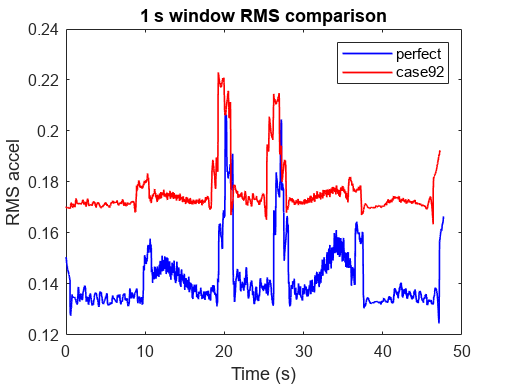


%% --- Feature Extraction Script (uses timeP/normP & timeC/normC) ---

% Sampling rate estimation
fs = 1/mean(diff(timeP));

%% 1. 1-second sliding window RMS
win_s = 1;
win_N = round(win_s * fs);
rmsP = sqrt( movmean(normP.^2, win_N, 'Endpoints','shrink') );
rmsC = sqrt( movmean(normC.^2, win_N, 'Endpoints','shrink') );

figure;
plot(timeP, rmsP, 'b-', 'LineWidth',1); hold on;
plot(timeC, rmsC, 'r-', 'LineWidth',1);
legend('perfect','case92');
xlabel('Time (s)'); ylabel('RMS accel');
title('1 s window RMS comparison');


%% 2. Kurtosis
kP = kurtosis(normP);
kC = kurtosis(normC);
fprintf('case-perfect kurtosis = %.2f\n', kP);

case-perfect kurtosis = 34.09


fprintf('case92 kurtosis = %.2f\n', kC);

case92 kurtosis = 56.18


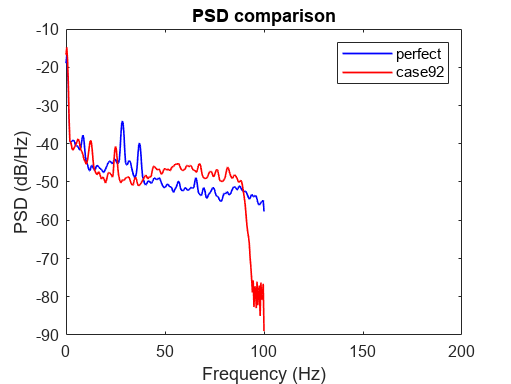


%% 3. Power Spectral Density (PSD)
nfft = 2^nextpow2(2*win_N);
[pxxP,f] = pwelch(normP, win_N, round(0.5*win_N), nfft, fs);
[pxxC,~] = pwelch(normC, win_N, round(0.5*win_N), nfft, fs);

figure;
plot(f,10*log10(pxxP),'b-', f,10*log10(pxxC),'r-','LineWidth',1);
xlim([0 200]);
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)');
legend('perfect','case92');
title('PSD comparison');


% Compute energy in 30–45 Hz band
fband = [30 45];
E_P = bandpower(pxxP, f, fband, 'psd');
E_C = bandpower(pxxC, f, fband, 'psd');
fprintf('30–45 Hz bandpower: perfect=%.3g, case92=%.3g\n', E_P, E_C);

30–45 Hz bandpower: perfect=0.00041, case92=0.000212


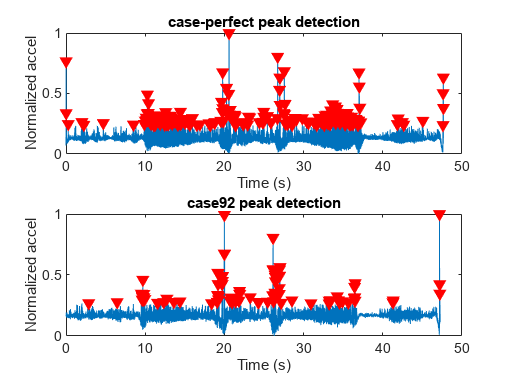


%% 4. Time domain peak detection
thrP = mean(normP) + 2*std(normP);
thrC = mean(normC) + 2*std(normC);
[pksP, locsP] = findpeaks(normP, timeP, 'MinPeakHeight', thrP);
[pksC, locsC] = findpeaks(normC, timeC, 'MinPeakHeight', thrC);

figure;
subplot(2,1,1);
plot(timeP, normP); hold on;
plot(locsP, pksP, 'rv','MarkerFaceColor','r');
title('case-perfect peak detection');
xlabel('Time (s)'); ylabel('Normalized accel');

subplot(2,1,2);
plot(timeC, normC); hold on;
plot(locsC, pksC, 'rv','MarkerFaceColor','r');
title('case92 peak detection');
xlabel('Time (s)'); ylabel('Normalized accel');


fprintf('case-perfect %d peaks detected\n', numel(pksP));

case-perfect 200 peaks detected


fprintf('case92 %d peaks detected\n', numel(pksC));

case92 79 peaks detected



%% Assume two Z-axis signals have been loaded and preprocessed:
%   timeP, normP    % case‐perfect time & normalized Z-axis
%   timeC, normC    % case92 time & normalized Z-axis

%% Assumptions:
sigP = normP;    sigC = normC;
labels = [0,1];  % 0 = perfect, 1 = defect
cases  = {sigP, sigC};
fs     = 1/mean(diff(timeP));
win_s  = 1;               % 1-second window
win_N  = round(win_s*fs);
step_N = win_N;

% --- 1. Estimate total number of windows ---
nwinP = floor((length(sigP)-win_N)/step_N) + 1;
nwinC = floor((length(sigC)-win_N)/step_N) + 1;
NwinTotal = nwinP + nwinC;

% --- 2. Preallocate X, y ---
nFeat = 9;  % 9 features extracted
X = zeros(NwinTotal, nFeat);
y = zeros(NwinTotal, 1);

% --- 3. Fill feature matrix ---
row = 1;
for ci = 1:2
    sig = cases{ci};
    lbl = labels(ci);
    nwin = floor((length(sig)-win_N)/step_N) + 1;
    for i = 1:nwin
        idx = (i-1)*step_N + (1:win_N);
        xw  = sig(idx);
        % ——— Feature Extraction ———
        f1 = rms(xw);
        f2 = skewness(xw);
        f3 = kurtosis(xw);
        f4 = max(abs(xw))/f1;              % Crest factor
        f5 = bandpower(xw, fs, [30 40]);   % Band power
        wpTree = wpdec(xw, 3, 'db4');
        E_low   = sum(wprcoef(wpTree,[3 0]).^2);
        E_mid1  = sum(wprcoef(wpTree,[3 1]).^2);
        E_mid2  = sum(wprcoef(wpTree,[3 2]).^2);
        E_high  = sum(wprcoef(wpTree,[3 3]).^2);

        % ——— Write to matrix ———
        X(row,:) = [f1 f2 f3 f4 f5 E_low E_mid1 E_mid2 E_high];
        y(row)   = lbl;
        row = row + 1;
    end
end

feature_names = {'RMS','Skew','Kurt','Crest','BP40_50','E_low','E_mid1','E_mid2','E_high'};

%% —— Feature Normalization —— (Z‐score)
mu = mean(X);
sigma = std(X);
Xn = (X - mu) ./ sigma;

%% —— Filter-based Feature Selection: Correlation Coefficient Method —— 
R = abs(corr(Xn, y));
[~, idxR] = sort(R, 'descend');
fprintf('Features sorted by correlation:\n');

Features sorted by correlation:


disp(feature_names(idxR));

    {'E_low'}    {'RMS'}    {'BP40_50'}    {'E_high'}    {'Skew'}    {'Crest'}    {'Kurt'}    {'E_mid1'}    {'E_mid2'}




%% —— Wrapper-based Feature Selection: Sequential Forward Selection —— 
cv = cvpartition(y,'KFold',5);
fun = @(XT,yT,Xt,yt) ...
      sum(predict(fitcsvm(XT,yT), Xt) ~= yt);
[selected, history] = sequentialfs(fun, Xn, y, 'cv',cv, 'direction','forward');
fprintf('Selected features (SFS):\n');

Selected features (SFS):


disp(feature_names(selected));

    {'Skew'}    {'E_low'}




%% —— Embedded Feature Selection: L1-Regularized Logistic Regression —— 
mdl = fitclinear(Xn, y, ...
         'Learner','logistic', ...
         'Regularization','lasso', ...
         'Lambda',0.01, ...
         'Solver','sparsa');
beta = mdl.Beta;
idxL = find(beta~=0);
fprintf('L1-Regularized selected features:\n');

L1-Regularized selected features:


disp(feature_names(idxL'));

    {'Crest'}    {'E_low'}    {'E_high'}



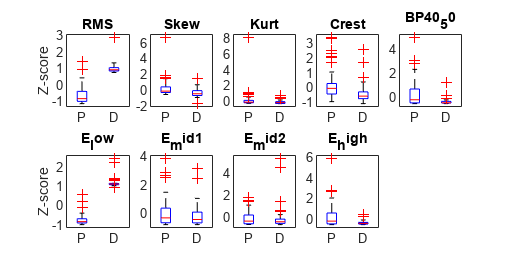


%% —— Boxplot Visualization for Selected Features —— 
figure('Position',[100 100 800 400]);
for i = 1:length(feature_names)
    subplot(2,5,i);
    boxplot(Xn(:,i), y, 'Labels',{'P','D'});
    title(feature_names{i});
    if i==1 || i==6, ylabel('Z-score'); end
end


%% —— Single Threshold Classification using E_low Z-score —— 
idxELow = strcmp(feature_names,'E_low');
E_low_z = Xn(:, idxELow);

pred = E_low_z <= 0;   % Defect = E_low_z < 0

TP = sum(pred==1 & y==1);
FP = sum(pred==1 & y==0);
TN = sum(pred==0 & y==0);
FN = sum(pred==0 & y==1);

fprintf('Classification using E_low Z-score threshold 0:\n');

Classification using E_low Z-score threshold 0:


fprintf('  TP = %d  FP = %d  TN = %d  FN = %d\n', TP, FP, TN, FN);

  TP = 0  FP = 45  TN = 2  FN = 29



accuracy  = (TP+TN)/(TP+TN+FP+FN);
recall    = TP / (TP + FN);
precision = TP / (TP + FP);
fprintf('  Accuracy = %.2f%%\n', 100*accuracy);

  Accuracy = 2.63%


fprintf('  Recall   = %.2f%%\n', 100*recall);

  Recall   = 0.00%


fprintf('  Precision= %.2f%%\n', 100*precision);

  Precision= 0.00%


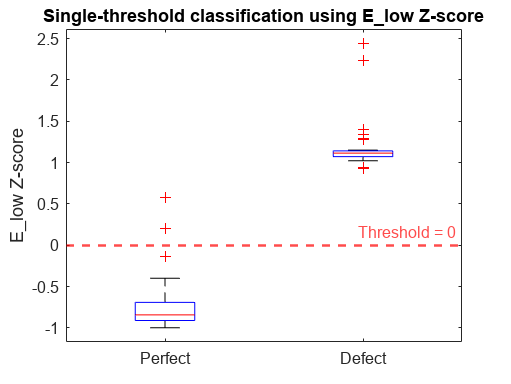


figure;
boxplot(E_low_z, y, 'Labels',{'Perfect','Defect'});
hold on;
yline(0, 'r--', 'Threshold = 0','LineWidth',1.5);
ylabel('E\_low Z-score');
title('Single-threshold classification using E\_low Z-score');


%% —— Full ML Model Script —— 

% Select feature (e.g., E_low)
idxELow = find(strcmp(feature_names,'E_low'));
Xsel = Xn(:, idxELow);  % Example using only E_low

% Split training/testing (80/20)
cvp = cvpartition(y,'HoldOut',0.2);
Xtr = Xsel(training(cvp),:);  ytr = y(training(cvp));
Xte = Xsel(test(cvp),:);      yte = y(test(cvp));

% Logistic Regression Training
mdlLR = fitclinear(...
    Xtr, ytr, ...
    'Learner','logistic', ...
    'Regularization','lasso', ...
    'Lambda',1e-3, ...
    'Solver','sparsa', ...
    'ClassNames',[0 1]);

% Predict on test set
[~, scoreLR] = predict(mdlLR, Xte);
yhatLR = scoreLR(:,2) > 0.5;

% Type alignment
yte_log   = logical(yte);
yhatLR_log= logical(yhatLR);

% Confusion Matrix & Metrics
C = confusionmat(yte_log, yhatLR_log);
TP = C(2,2); FP = C(1,2);
FN = C(2,1); TN = C(1,1);

accuracy  = (TP+TN)/sum(C,'all');
recall    = TP/(TP+FN);
precision = TP/(TP+FP);
f1_score  = 2*(precision*recall)/(precision+recall);

fprintf('--- Logistic Regression Test Performance ---\n');

--- Logistic Regression Test Performance ---


fprintf(' TP=%d  FP=%d  TN=%d  FN=%d\n', TP,FP,TN,FN);

 TP=6  FP=0  TN=9  FN=0


fprintf(' Accuracy = %.2f%%\n', accuracy*100);

 Accuracy = 100.00%


fprintf(' Recall   = %.2f%%\n', recall*100);

 Recall   = 100.00%


fprintf(' Precision= %.2f%%\n', precision*100);

 Precision= 100.00%


fprintf(' F1 score = %.2f\n\n', f1_score);

 F1 score = 1.00




% ROC & AUC
[~,~,~,AUC] = perfcurve(yte_log, scoreLR(:,2), true);
fprintf(' Logistic Regression AUC = %.3f\n', AUC);

 Logistic Regression AUC = 1.000



figure;
plotroc(ind2vec(yte_log'+1), ind2vec(yhatLR_log'+1));
title(sprintf('Logistic ROC (AUC = %.3f)', AUC));

% SVM Training & Cross Validation
mdlSVM = fitcsvm(...
    Xtr, ytr, ...
    'KernelFunction','linear', ...
    'Standardize', true, ...
    'ClassNames',[0 1]);

CVSVM = crossval(mdlSVM,'KFold',5);
svmCVError = kfoldLoss(CVSVM);
fprintf('5-fold CV Linear SVM error = %.2f%%\n\n', svmCVError*100);

5-fold CV Linear SVM error = 1.64%




% Test set evaluation
[~, scoreSVM] = predict(mdlSVM, Xte);
yhatSVM = scoreSVM(:,2) > 0;
yhatSVM_log = logical(yhatSVM);

C2 = confusionmat(yte_log, yhatSVM_log);
TP2 = C2(2,2); FP2 = C2(1,2);
TN2 = C2(1,1); FN2 = C2(2,1);
acc2 = (TP2+TN2)/sum(C2,'all');
fprintf('--- Linear SVM Test Performance ---\n');

--- Linear SVM Test Performance ---


fprintf(' TP=%d  FP=%d  TN=%d  FN=%d\n', TP2,FP2,TN2,FN2);

 TP=6  FP=0  TN=9  FN=0


fprintf(' Accuracy = %.2f%%\n', acc2*100);

 Accuracy = 100.00%



% SVM Decision Boundary Visualization (2D example)
if size(Xsel,2) >= 2
    figure;
    gscatter(Xte(:,1), Xte(:,2), yte_log, 'br', 'ox');
    hold on;
    d = 0.01;
    [x1Grid,x2Grid] = meshgrid(min(Xte(:,1))-1:d:max(Xte(:,1))+1, ...
                              min(Xte(:,2))-1:d:max(Xte(:,2))+1);
    xGrid = [x1Grid(:), x2Grid(:)];
    [~,scoresGrid] = predict(mdlSVM, xGrid);
    contour(x1Grid, x2Grid, reshape(scoresGrid(:,2), size(x1Grid)), [0 0], 'k');
    xlabel(feature_names{idxELow});
    ylabel(feature_names{idxBP});
    title('Linear SVM Decision Boundary (Test Set)');
    legend('Perfect','Defect','Decision Boundary','Location','best');
end

